% animation of a particle moving in 2d
clear;
clc;
close all;

% define the domain
t = linspace(0, 2*pi, 1000); % this corresponds to r^1

% define the mapping
x = cos(t);
y = sin(t);

for k = 1:10:length(t)
    % clean to get a new plot
    clf;

    % get data for a instant k
    t_k = t(k);
    x_k = x(k);
    y_k = y(k);


    % plot the location of the particle at time k
    plot(x_k, y_k, '.r', 'MarkerSize', 100)

    % keep the actual plot when adding new ones
    hold on;

    % display a grid to better study movement
    grid on;

    % plot the full trajectory
    plot(x, y, 'k');

    % set axes name
    xlabel('x');
    ylabel('y');


    % set plot title
    title(['Particle at t = ' num2str(t_k), ' seconds']);

    % set both x and y axis the same size
    axis equal;
    
    % force matlab to draw the image at that point
    drawnow;
end

Animation of the circle in 3d

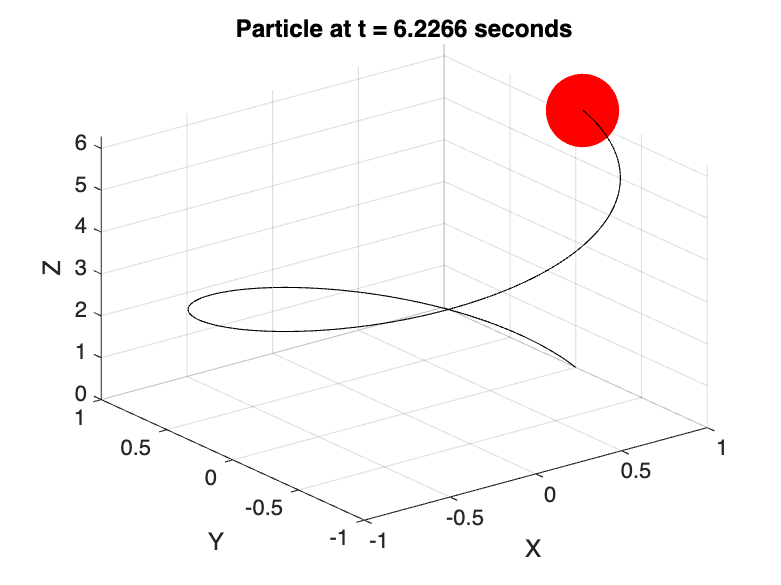

clear;
clc;
close all;

% Define the domain
t = linspace(0, 2*pi, 1000);

% Define the mapping
x = cos(t);
y = sin(t);
z = (t);

figure;


for k = 1:10:length(t)
    % Clear figure
    clf;
    
    % Get data for instant k
    t_k = t(k);
    x_k = x(k);
    y_k = y(k);
    z_k = z(k);
    
    
    % Plot the current position of the particle
    plot3(x_k, y_k, z_k, '.r', 'MarkerSize', 100);
    hold on;
    grid on;

    % Set labels and title

    plot3(x,y,z, 'k')
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title(['Particle at t = ' num2str(t_k) ' seconds']);   
    
    % Draw the current frame
    drawnow;

    % save the animation frames
    % vectorAnimation(end+1) = getframe(gcf);  
end


% Create video writer object
% miAnimacion = VideoWriter("circle_animation", "MPEG-4");
% miAnimacion.FrameRate = 20;

% Open the VideoWriter object
% open(miAnimacion);
% writeVideo(miAnimacion, vectorAnimation);
% close(miAnimacion);
